% set your MATLAB root dir>
rootDir = 'C:\Users\Admin\Documents\Matlab Code';

% set your variables>
dataDir = 'C:\Users\Admin\Documents\Projects\Sae\101119_V2.4_AldCreTam\Taillift_1_-669um_001'; % full address of where the file is
dataFile = 'Values';  %% no values file - where is average fluor being calculated
frRate = 0.55578697729921; % seconds/frame
blStartFr =1;
blFramesN = 1; % n of frames over which you calculate F0

% set tailLift Time in sec>
%% [first in sec]:[interval in sec]:[last in sec]
%% 60:60:240 will assign one taillift every 60 seconds starting at and including 
%% 60 and ending at and including 240 (60, 120, 180, 240)
markerSec = 60:60:240;

% import data from excel>
fileName = [dataDir,'\',dataFile,'.csv'];
[N,T,~] = xlsread(fileName); 
    % remove first column>
    if isequal(T(1),{'X'}) || isequal(T(1),{' '})
       T = T(:,2:end);
       N = N(:,2:end);
    end
T=T'; N=N';
frN = size(N,2);
    
% % remove "Mean()":
% for k = 1:length(T)
%     oldStr = T(k);
%     removeStr = ["Mean(",")"];
%     newStr = erase(oldStr,removeStr);
%     T(k) = newStr;
% end

% create time vector:
TimeS = frRate:frRate:frRate*frN;
% trace>
fluoTrace = N;

% calculate dFF (= (F-F0)/F0):
dFFwindowFr = blStartFr:blStartFr+blFramesN-1;
    F0 = mean(fluoTrace(:,dFFwindowFr),2); 
    dFF = (fluoTrace-F0)./F0; 

% save traces/time>
cd(dataDir)
save('exptTrace',...
     'fluoTrace','dFF','TimeS')
cd(rootDir)


clear T N

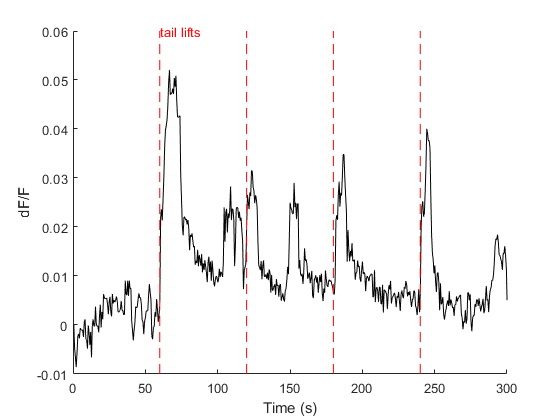

% plot
figure;
plot(TimeS, dFF, 'Color','k')
hold on

xlabel('Time (s)')
ylabel('dF/F')
box off

xlim([0 round(TimeS(end))])

% get range of y axis for plotting lines>
yRange = ylim;
yMin = yRange(1);
yMax = yRange(2);

% plot lines to mark tailLift times>
for i = 1:numel(markerSec)
    a = markerSec(i);
    line([a a],[yMin yMax],...
        'color','r','LineStyle','--')
    if i ==1 
       text(a,yMax,'tail lifts','Color','r')
    end
end